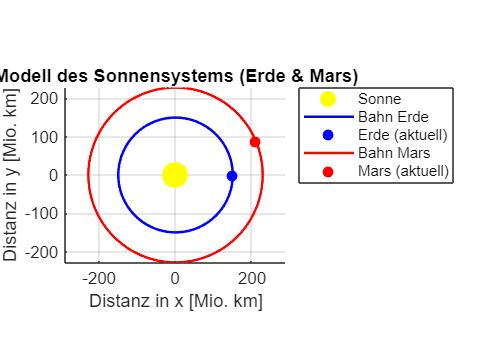

% Skript: Sonnensystem_Modell.m
% Beschreibung: Einfaches numerisches Modell von Erde und Mars (Kreisbahnen)
clear; clc; close all;

%% 1. Parameter definieren (Quelle: Wikipedia)
% Erde
R_Erde = 149.6;     % Mittlerer Bahnradius in Mio. km
T_Erde = 365.25;    % Umlaufzeit in Tagen

% Mars
R_Mars = 227.9;     % Mittlerer Bahnradius in Mio. km
T_Mars = 687;       % Umlaufzeit in Tagen (gerundet)

%% 2. Berechnung der Winkelgeschwindigkeiten
% omega = 2 * pi / T
w_Erde = 2 * pi / T_Erde;
w_Mars = 2 * pi / T_Mars;

%% 3. Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:1:730; 

%% 4. Berechnung der Bahnkurven (Trajektorien)
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

% Beschriftung
xlabel('Distanz in x [Mio. km]');
ylabel('Distanz in y [Mio. km]');
title('Modell des Sonnensystems (Erde & Mars)');
legend('Location', 'northeastoutside');

hold off;